# 2. Graph capillaries from OCT microangiogram

## 1. Initiate.

Select microangiogram data to load. 

- aid = Analysis ID : The result from this analysis of multiple datasets will be saved with `aid`.

- Make sure that glass does not intersect with cortex.

%comInit;

aid = '180223_AD6'; 

uid = 'kwalek';  % user ID
eid = '180223_AD6';  % Expr ID list
pid = 'AD6_wk34_mangio1';

uid2 = 'sabina'; %under which user id do you want to store data?
pathraw = ['D:/' uid '/' eid]; 

pathdata = ['D:/' uid2 '/' eid]; % path to save reconstructed data
if isempty(dir(pathdata))
    mkdir(pathdata)
end

disp('Init complete')

Init complete


## 2. Load microangiogram data 

disp('Data loading ...');

Data loading ...


load([pathraw '/' pid '.mat'],'DD', 'conf', 'II');
disp([datestr(now,'HH:MM') ' data loaded.']);

12:45 data loaded.


load('net_reg'); %regression (EnmhVess)
load('net12_16_final.mat'); %segmentation (SegVess)
disp("SECTION COMLPETED")

## 3. Select Region of Interest (ROI)

- If desired, sellect a region of interest by drawing a rectangle. If you wish to process the entire image, skip this section.

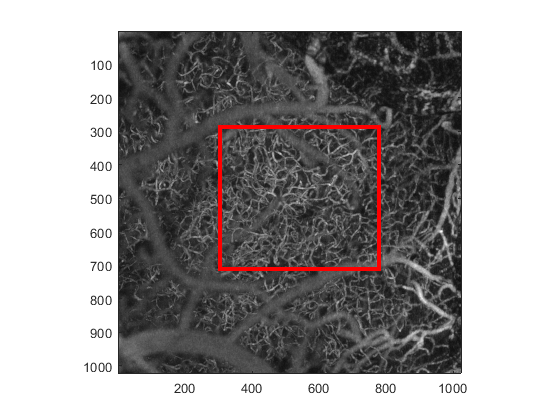


Select_ROI;

mip = squeeze(max(log(DD),[],1));
figure(1); imagesc(squeeze((mip)))
colormap(gray)
axis image
hold on; rectangle('Position', [y1, x1, y2-y1, x2-x1], 'EdgeColor','r', 'LineWidth', 3);


DD = DD(:,x1:x2,y1:y2);
II = II(:,x1:x2, y1:y2);
disp("SECTION COMLPETED")

## 4. Apply enhancement CNN (EnhVess).

- Data is pre-processed using filtering, and a microangiogram is enhanced using EnhVess.

- Takes about ~1min


sf1 = sf_ind(DD);

for i = 1:size(DD,2)
    for j = 1:size(DD,3)
        DD(1:sf1(i,j) + 10,i,j) = 0;
    end
end
DD(DD == 0) = mean(DD(DD(:)~=0));

logDD = log(DD);
logDD = mat2gray(logDD);

[s1, s2, s3] = size(DD);
m1 = mod([s1 s2 s3],32);
p1 = 0; p2 = 0; p3 = 0;

if m1(1) > 0
    p1 = 32-m1(1);
end

if m1(2) > 0
    p2 = 32-m1(2);
end

if m1(3) > 0
    p3 = 32-m1(3);
end

if sum(m1) > 0
    logDD = padarray(logDD, [p1 p2 p3], 'post');
end


Enh = activations(net_reg, logDD, 'regressionoutput', 'executionenvironment', 'cpu');
Enh = Enh(1:s1,1:s2,1:s3);
logDD = logDD(1:s1,1:s2,1:s3);

disp("SECTION COMLPETED")

## 5. Crop Depth

Use the slider to scan through the depth, and assess the depth of interest - where does the microvascular bed start and end? Once you quit the slider, select the depth of interest using the Intensity profile to guide you.

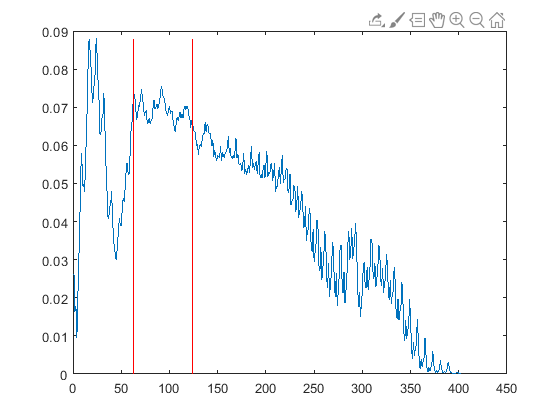

GUI_slider(permute(Enh, [2 3 1]));

Crop_depth

Enh = Enh(z1:z2,:,:);
logDD = logDD(z1:z2,:,:);
II = II(z1:z2,:,:);
disp("SECTION COMLPETED")


### 5. Apply Segmentation network (SegVess)

- Takes about ~3min

tic
[s1, s2, s3] = size(Enh);
m1(1) = mod(s1,12);
m1(2) = mod(s2,16);
m1(3) = mod(s3,16);
p1 = 0; p2 = 0; p3 = 0;

if m1(1) > 0
    p1 = 12-m1(1);
end

if m1(2) > 0
    p2 = 16-m1(2);
end

if m1(3) > 0
    p3 = 16-m1(3);
end

if sum(m1) > 0
    Enh = padarray(Enh, [p1 p2 p3], 'post');
end

seg_approx = semanticseg(Enh,net12_16_final, 'executionenvironment', 'cpu');
seg_approx = double(seg_approx) - 1;
seg = imclose(seg_approx,ones(3,3,3));

seg = seg(1:s1,1:s2,1:s3);
Enh = Enh(1:s1,1:s2,1:s3);


seg = imgaussfilt3(seg,1) > 0.3;

mip = squeeze(max(seg,[],1));
figure; imagesc(squeeze((mip)))
colormap(gray)
axis image
toc
disp("SECTION COMLPETED")

## 6. Apply connectivity-enhancing network (ConVess) 

- Connectivity-enhancing network uses underlying data (OCTA and enhanced OCTA) to guide gap correction of the segmentation from the previous step.

- Edges are smoothed, and isolated components smaller than 50px are removed.

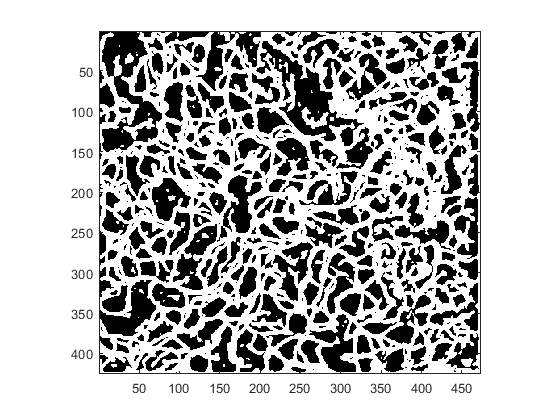

tic
load('corrnet_3layers.mat')

clear c;

Elapsed time is 74.350478 seconds.


c(:,:,:,1) = mat2gray(logDD);
c(:,:,:,2) = Enh;
c(:,:,:,3) = seg;
seg_corr = activations(corrnet,c,'dice', 'executionenvironment','cpu');
seg2 = max(seg_corr(1:s1,1:s2,1:s3,2),seg);
seg2 = seg2>0.3;
seg2 = imclose(seg2,ones(3,3,3));


%remove any small unconnected components
CC  = bwconncomp(seg2);
numPixels = cellfun(@numel,CC.PixelIdxList);
ind = find(numPixels > 100);
res = zeros(size(seg2));
for i = 1:length(ind)
    res(CC.PixelIdxList{ind(i)}) = 1;
end

mip = squeeze(max(res,[],1));
figure; imagesc(squeeze((mip)))
colormap(gray)
axis image
toc
disp("SECTION COMLPETED")

## 7. Skeletonization

- Skeletonization following several steps: first the segmentation is thinned to produce a skeleton, which is then recentered. The skeleton is resized to produce an isotropic image. Spurious branches are removed based on how Gaussian they appear, and small unconnected branches are removed.

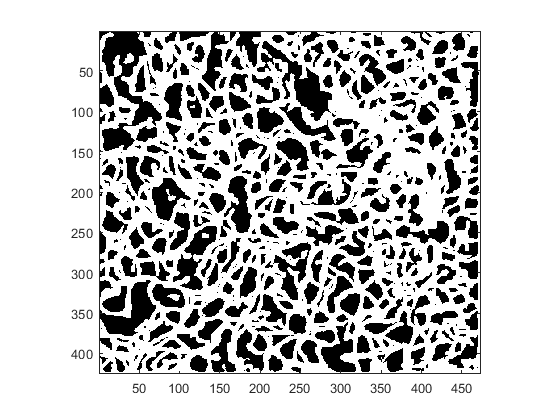


skel = make_skel(res,Enh); % ~50min %skeletonization and recentering

if exist('conf.dx', 'var') == 0
    conf.dx = 1.5;

    conf.dy = 1.5;

Elapsed time is 9.324199 seconds.


end

fszx = 3.5/conf.dx;
fszy = 3.5/conf.dy;

V = imresize3(Enh, [size(Enh,1), round(size(Enh,2)/fszx) round(size(Enh,3)/fszy)]); %resize to make isotropic
skel1 = imresize3(imdilate(skel, ones(3,3,3)), [size(Enh,1), round(size(Enh,2)/fszx) round(size(Enh,3)/fszy)]);

Recentering #1...
Iteration: 1
Iteration: 2
Iteration: 3
Iteration: 4
Iteration: 5
Iteration: 6
Iteration: 7
Iteration: 8
Iteration: 9
Iteration: 10
Iteration: 11
Iteration: 12
Iteration: 13
Iteration: 14
Iteration: 15
Iteration: 16
Iteration: 17
Iteration: 18
Iteration: 19
Iteration: 20
Iteration: 21
Iteration: 22
Iteration: 23
Iteration: 24
Iteration: 25
Iteration: 26


skel1 = skel1>0.5;
skel1 = imclose(skel1, ones(3,3,3));
skel1 = bwskel(skel1, "MinBranchLength",7);
S1 = rem_small(skel1); %~ 5min


%removing spurious branches

O = rem_nongauss_whole(S1,V); 


skel2 = rem_loop(S1,O, skel1); %removes spurious branches
skel3 = rem_seq(skel2) %removes endpoints < 7px
S3 = rem_small(skel3);
S = S3; skel = skel3;

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


disp("SECTION COMLPETED")

## 8. Automated vessel connection using Tensor Voting (Optional)

- This will aim to automatically connect endpoints based on tensor voting. This can connect many free ends, making manual correction take less time.

res2 = imresize3(res, [size(res,1), round(size(res,2)/fszx) round(size(res,3)/fszy)]); 

Processed: 200/1477


Processed: 400/1477


Processed: 600/1477


Processed: 800/1477


res2 = res2>0.1;
[skel3, Sc] = main_tensor_connect(skel3,S3,res2); %~1 min
S3 = rem_small(skel3);
S = S3; skel = skel3;
disp("SECTION COMLPETED")

## 8. Manual inspection and correction

You will be shown an image of about 100 x 100 pixels (en face slice) of the microangiogram with the vessel segments overlaid. 

- To scan through the depth: use z and x.

- To delete a vessel segment, click the vessel segment and press backspace.

- To "undo" a deleted vessel, press "v".

- Pay extra attention to vessels that are bounded by a red rectangle. These vessels have an unconnected endpoint.

- Once you click on a vessel, it will show you which other vessels it is connected to.

- To connect two vessel segments: 

-  Make sure that neither of the two vessels are currently selected (click away or on a different vessel if necessary), 

- Click on the button "Connect vessels"

- Click on the vessel segment with the endpoint you would like to connect, and then click on the second vessel you would like to connect it to.

- To create a new vessel segment:

- Press "enter".

- To create a point, click.

- If neccessary, use x and z to change the depth.

- Create connecting points by clicking. Lines between the points will be automatically created.

- To complete this process, press "enter" again.

- Don't forget to connect this vessel segment to other vessel segments by clicking "connect vessels"

- Once you are done with this square, close the window by clicking the 'x' in the right hand corner. A new window will automatically pop up. Repeat this process with the next window. 

- Once the entire image is processed, no new windows will pop up.

- If you wish to see the entire image at once, change the value of large_FOV to equal 1. Note that this may be slower.

- You can click "Quit" and it will save your work in the workspace. When you are ready to continue, just start this section again. To quit the entire analysis and return at a later stage, see Section 12.

large_FOV = 0; % or else make this equal to 1 for large field of view

if large_FOV == 1

Creating scalar field
100/1347
200/1347
300/1347
400/1347
500/1347
600/1347
700/1347
800/1347
900/1347
1000/1347
1100/1347
1200/1347
1300/1347
Connecting endpoints using scalar field


    S = manual_inspection_large_FOV(S, V);
else
    S = manual_inspection(S, skel,V);
end
skel = seg2skel(S, V);
S = rem_small(skel);

## 9. Calculate vascular properties

- Vascular properties to be calculated: 

- Diameter

- Length

- Tortuosity

- Network properties

- Fractional dimension


Main_length; % ~2s
Main_diam; % ~15min
Main_tortuosity;  %~1min
Network_analysis; %~2min
[n,r] = boxcount(seg);
powfunc = fittype('n0*r^(-frac)',...
    'dependent',{'y'},'independent',{'r'},...
    'coefficients',{'n0','frac'});
pow_fit = fit(r',n',powfunc, 'startpoint', [max(n) 3]);

Starting parallel pool (parpool) using the 'local' profile ...


frac = pow_fit.frac;

## 10. Branching order: identify penetrating arterioles

- Please click on penetrating arterioles, which look like dark circles and are larger than capillaries.


find_penetrating_art;
mip = squeeze(min((II1(end-10:end,:,:)),[],1));

100/494
200/494
300/494
400/494


figure; imagesc(squeeze((mip)))

100/494
200/494
300/494
400/494


colormap(gray)
axis image
hold on
scatter(X,Y, 'x', 'r')

branching_order; %~6min



## 11. Save analysis

Analysis will be saved as an excel file with 3 sheets:

- the first sheet provides diameter, length, and tortuosity

- the second sheet provides vessels per branching order

- the third sheet provides network properties

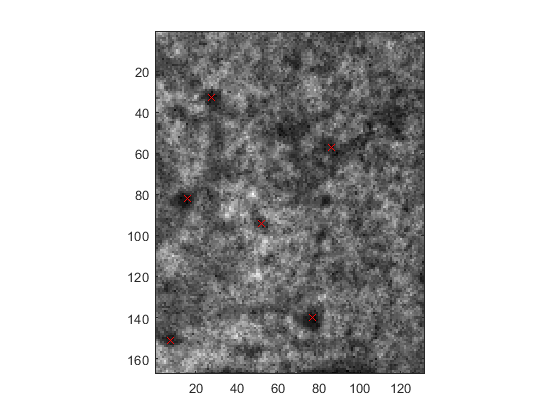

disp('Saving Analysis ...');

filename = [pathdata '/properties.xls'];
dat_geo = table(D, tort, full_l, 'variablenames', {'Diameter', 'Tortuosity', 'Length'});
dat_branch = table(branch, 'variablenames', {'branching order'});
writetable(dat_geo,filename)
writetable(dat_branch,filename,'sheet', 2);


dat_topo = table(metrics.clsness, metrics.btwness, metrics.assortativityByNode, metrics.eigenCentralities, 'variablenames',{'Closeness', 'Betweenness', 'Assortativity', 'EigenCentralities'});
writetable(dat_topo,filename,'sheet', 3);
dat_frac = table(frac, 'variablenames',{'fractal dimension'});
writetable(dat_frac, filename, 'sheet', 4)
save('-v7.3',[pathdata '/' aid '.mat']);

disp('Analysis Saved.');
disp(['Recommended report file name:' char(10) '2 Process - ' uid ' - ' eid ' - ' aid '.pdf']);

You may also want to export this analysis to a report in PDF. Run *Live Editor > Save > Export to PDF*.

**Please do *****not *****save report files under GitHub folders**. Recommened are:

- Space: *\\files.brown.edu\research\ENG_Lee-Lab_Shared\group\report\cvi-18-3d\DLS-OCT*

- You can copy the path of space and paste it into the export window.

- File name: printed above

## 12. Save workspace (read below)

 If you would like to save your work so far so that you can quit MATLAB and/or continue this analysis at a later stage, run this section. If you would like to continue the analysis, run Section 13, and continue from where you left off. If you have completed the analysis already, do not run this section - your work has already been saved in Section 11.

save('-v7.3',[pathdata '/' aid '.mat']);

Saving Analysis ...


## 13. Load a saved analysis for review.

Select an analysis to load. To review the loaded analysis, proceed to the following subsections. 

If you want to re-analyze the data, you can go back to the revelant sections  adjust the parameters, run again. When you re-analyzed, it is recommended to save the analysis with a different *aid*.


uid = 'sabina';  % User ID
eid = 'AD6_wk30';  % Experiment ID
aid = 'AD6_wk30_mangio1_a1';  % Analysis ID

pathdata = ['D:/' uid '/' eid]; % path to save reconstructed data
disp('Loading Analysis ...');
load([pathdata '/' aid '.mat']);
disp('Analysis Loaded.');

Analysis Saved.


Recommended report file name:
2 Process - kwalek - 180122_AD6 - AD6_wk30_mangio1_a1.pdf
